# Dynamic programming algorithm

In this live script we discuss an implementation of the dynamic programming algorithm for general discrete optimization problems. 

Let us start by recalling the formulation of a discrete optimization problem


$$$$ \min  \sum_{k=0}^{h-1} g_k( x_k, u_k ) + g_h( x_h )$$ $$


subject to


$$$$ x_{k+1} = f_k( x_k, u_k ),$$$$


﻿where $$k\in K:=\{0,1,2,\dots,h-1\}$$, $$x_k\in X_k:=\{1,2,\dots,n_k\}$
$, for $$k\in K \cup \{h\}$$ and $$u_k \in U_K(x_k):=\{1,2,\dots,m_k(x_k)\}$$ for $$k\in K$$ and $$x_k \in X_k$$.

We need to find a good representation for this problem in terms of Matlab data structures. To this effect consider the following data structures, which fully characterize the optimal control problem:

- ﻿M - cell object such that M{k+1}{i}{j} = $$f_k(i,j)$$;

- C- cell object such that C{k+1}{i}{j} = $$g_k(i,j)$$;

- T- vector such that T(i)=$$g_h(i), \ \ i\in X_h$$;

The dynamic programming algorithm will result in an optimal policy and in  costs-to-go. These can be specified by the following data structures:

- $$J$$ - cell object such that $$J\{k+1\}\{i\}$$ is the cost-to-go at stage $$k$$, $$k\in K $$, and state $$i$$; Note that the terminal cost is not included.

- $$u$$ - cell object such that $$u\{k+1\}\{i\}$$ is a vector of indices $$j$$  corresponding to the optimal actions (possibly more than one) for each stage $$k$$, $$k\in K $$,  and state $${i}$$. 

The function dptv.m below implements the dynamic programming algorithm given the mentioned inputs representing the problem and provides the mentioned outputs characterizing the optimal policies (possibly more than one) and costs-to-go. To test it, we can use the following example, corresponding to the plot in Figure 1 (states correspond to circles, actions to arrows-action 1 corresponds to the top arrow and action $$m_k(x_k)$$to the bottom arrow) 

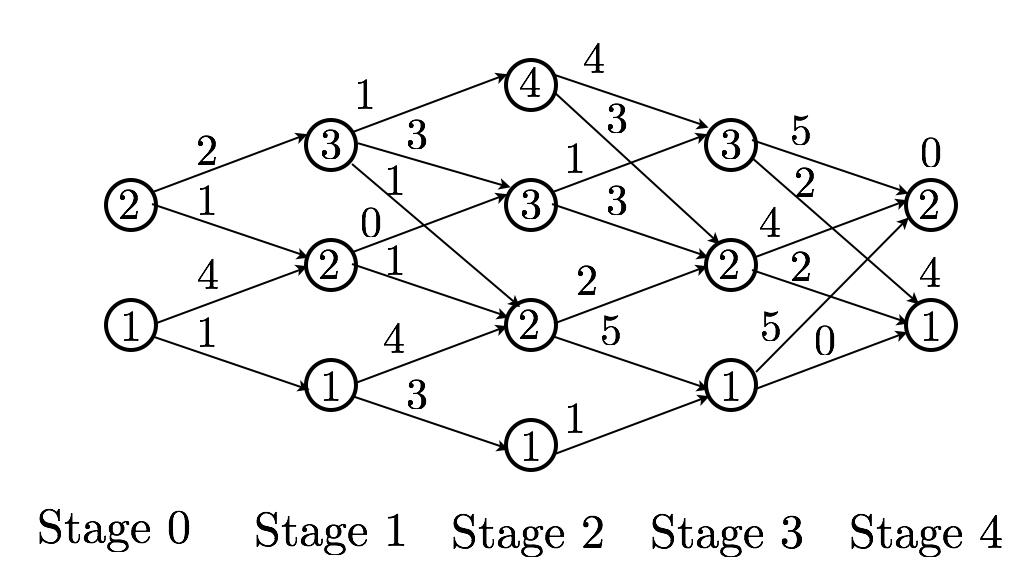

Figure 1: Transition diagram of the example% stage 0

C{1}{1}{1} = 1; M{1}{1}{1} = 1;
C{1}{1}{2} = 4; M{1}{1}{2} = 2;
C{1}{2}{1} = 1; M{1}{2}{1} = 2;
C{1}{2}{2} = 2; M{1}{2}{2} = 3;

% stage 1
C{2}{1}{1} = 3; M{2}{1}{1} = 1;
C{2}{1}{2} = 4; M{2}{1}{2} = 2;
C{2}{2}{1} = 1; M{2}{2}{1} = 2;
C{2}{2}{2} = 0; M{2}{2}{2} = 3;
C{2}{3}{1} = 1; M{2}{3}{1} = 2;
C{2}{3}{2} = 3; M{2}{3}{2} = 3;
C{2}{3}{3} = 1; M{2}{3}{3} = 4;

% stage 2
C{3}{1}{1} = 1; M{3}{1}{1} = 1;
C{3}{2}{1} = 5; M{3}{2}{1} = 1;
C{3}{2}{2} = 2; M{3}{2}{2} = 2;
C{3}{3}{1} = 3; M{3}{3}{1} = 2;
C{3}{3}{2} = 1; M{3}{3}{2} = 3;
C{3}{4}{1} = 3; M{3}{4}{1} = 2;
C{3}{4}{2} = 4; M{3}{4}{2} = 3;

% stage 3
C{4}{1}{1} = 0; M{4}{1}{1} = 1;
C{4}{1}{2} = 5; M{4}{1}{2} = 2;
C{4}{2}{1} = 2; M{4}{2}{1} = 1;
C{4}{2}{2} = 4; M{4}{2}{2} = 2;
C{4}{3}{1} = 2; M{4}{3}{1} = 1;
C{4}{3}{2} = 5; M{4}{3}{2} = 2;

% terminal cost
Jh = [4;0]';
h = 4;
[u,J] = dptv( M, C, Jh);

% print (remove while testing with other inputs)

fprintf('                        u_2(4): %i            \n', u{3}{4})

                        u_2(4): 1            


fprintf('           u_1(3): %i, u_2(3): %i, u_3(3): %i\n', u{2}{3},u{3}{3},u{4}{3})

           u_1(3): 1, u_2(3): 2, u_3(3): 2


fprintf('u_0(2): %i, u_1(2): %i, u_2(2): %i, u_3(2): %i\n', u{1}{2},u{2}{2},u{3}{2},u{4}{2})

u_0(2): 1, u_1(2): 2, u_2(2): 2, u_3(2): 2


fprintf('u_0(1): %i, u_1(1): %i, u_2(1): %i, u_3(1): %i\n', u{1}{1},u{2}{1},u{3}{1},u{4}{1})

u_0(1): 1, u_1(1): 1, u_2(1): 1, u_3(1): 1



fprintf('                        J_2(4): %i            \n', J{3}{4})

                        J_2(4): 7            


fprintf('           J_1(3): %i,  J_2(3): %i, J_3(3): %i\n', J{2}{3},J{3}{3},J{4}{3})

           J_1(3): 7,  J_2(3): 6, J_3(3): 5


fprintf('J_0(2): %i, J_1(2): %i, J_2(2): %i, J_3(2): %i\n', J{1}{2},J{2}{2},J{3}{2},J{4}{2})

J_0(2): 7, J_1(2): 6, J_2(2): 6, J_3(2): 4


fprintf('J_0(1): %i, J_1(1): %i, J_2(1): %i, J_3(1): %i\n', J{1}{1},J{2}{1},J{3}{1},J{4}{1})

J_0(1): 9, J_1(1): 8, J_2(1): 5, J_3(1): 4


The result, i.e., the optimal policy and the costs-to-go are depicted in Figure 2 (costs-to-go on top, and optimal policy specified by the arrows).

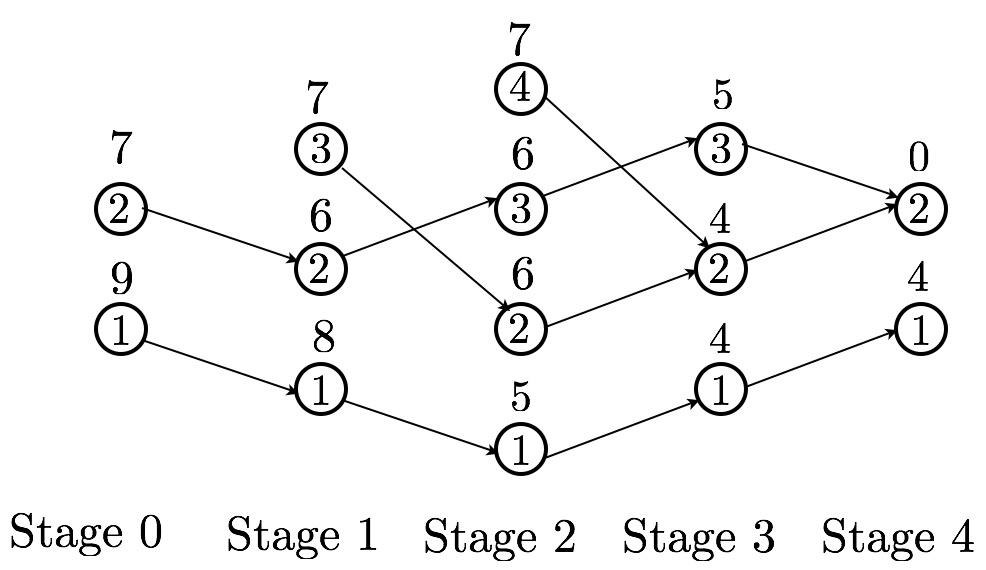

Figure 2: Optimal policy and costs-to-go

function [u,J] = dptv( M, C, T)
h = length(M);
for l = 1:length(T)
    J_{h+1}{l} = T(l);
end
for k = h:-1:1
    ni = length(M{k}); % state dimension
    for i=1:ni
        nj = length(M{k}{i});
        caux = zeros(1,nj);
        for j = 1:nj
            caux(j) = C{k}{i}{j} + J_{k+1}{M{k}{i}{j}};
        end
        [a,b] = sort(caux);
        J_{k}{i} = a(1); J{k}{i} = J_{k}{i};
        u{k}{i}(1) = b(1);
        for ell = 2:length(a)
            if abs( a(ell) - a(1))<1e-8
                u{k}{i}(ell) = b(ell);
            else
                break;
            end
        end
    end
end
end